## First test with the TDL channel 

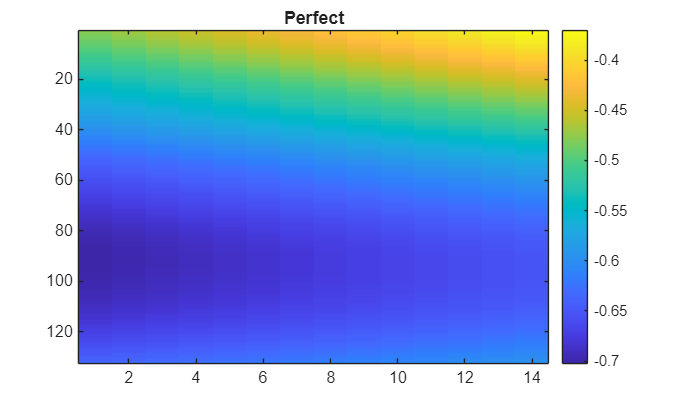

ue = nrCarrierConfig;
ue.NSizeGrid = 11;          % Bandwidth in number of resource blocks (52RBs at 15kHz SCS for 10MHz BW)
ue.SubcarrierSpacing = 15;  % 15, 30, 60, 120, 240 (kHz)
ue.CyclicPrefix = 'Normal'; % 'Normal' or 'Extended'

nTxAnts = 1;  % Number of transmit antennas
nRxAnts = 1;  % Number of receive antennas
nLayers = min(nTxAnts,nRxAnts);

channel = nrTDLChannel;
channel.DelayProfile = 'TDL-C';
channel.DelaySpread = 40e-9;
channel.MaximumDopplerShift = 30;
channel.NumTransmitAntennas = nTxAnts;
channel.NumReceiveAntennas = nRxAnts;
channel.Seed = 5;

% Set channel sample rate
ofdmInfo = nrOFDMInfo(ue);
channel.SampleRate = ofdmInfo.SampleRate;

% Get the maximum delay of the channel
chInfo = info(channel);
maxChDelay = chInfo.MaximumChannelDelay;

% Reset random generator for reproducibility
rng('default');

% Create a slot-wise resource grid empty grid
txGrid = nrResourceGrid(ue,nTxAnts);

txGrid1 = ones(size(txGrid));
[txWaveform1,~] = nrOFDMModulate(ue,txGrid1);
txWaveform1 = [txWaveform1; zeros(maxChDelay, size(txWaveform1,2))];

pathFilters = getPathFilters(channel);
[rxWaveform1,pathGains] = channel(txWaveform1);
offset = nrPerfectTimingEstimate(pathGains,pathFilters);
rxGrid1 = nrOFDMDemodulate(ue,rxWaveform1(1+offset:end,:));
hEstPerfect = nrPerfectChannelEstimate(ue,pathGains,pathFilters,offset);    

figure; imagesc(real(hEstPerfect)); colorbar; title('Perfect')

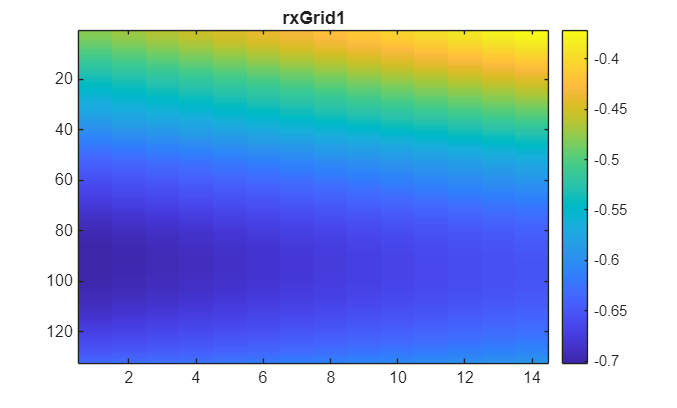

figure; imagesc(real(rxGrid1)); colorbar; title('rxGrid1')

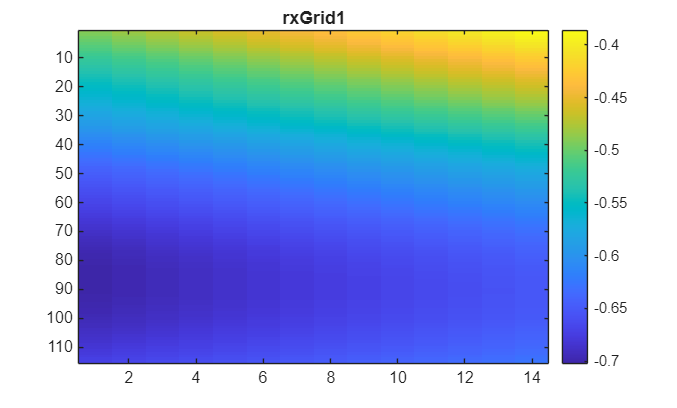

figure; imagesc(real(rxGrid1(6:120,:))); colorbar; title('rxGrid1')

Elements at 2 edges of the bandwidth are quite off the range - if we cut off these elements, the range of the txGrid is mostly similar to the channel got from nrChannelEstimate

## Now test with NTN-TDL channel

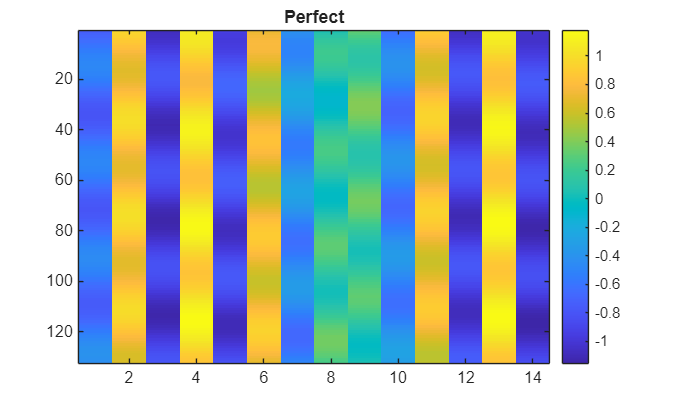

simParameters.CarrierFrequency = 21e9; %19e9; % 2.18e9;                  % Carrier frequency (in Hz)
simParameters.SatelliteAltitude = 1000000;

simParameters.ElevationAngle = 50;                     % Elevation angle (in degrees)
simParameters.MobileSpeed = 5*1000/3600;               % Speed of mobile terminal (in m/s)
simParameters.MobileAltitude = 0;

ue = nrCarrierConfig;
ue.NSizeGrid = 11;          % Bandwidth in number of resource blocks (52RBs at 15kHz SCS for 10MHz BW)
ue.SubcarrierSpacing = 120;  % 15, 30, 60, 120, 240 (kHz)
ue.CyclicPrefix = 'Normal'; % 'Normal' or 'Extended'

waveformInfo = nrOFDMInfo(ue);
simParameters.SampleRate = waveformInfo.SampleRate;
c = physconst("lightspeed");
satelliteDopplerShift = dopplerShiftCircularOrbit( ...
    simParameters.ElevationAngle,simParameters.SatelliteAltitude, ...
    simParameters.MobileAltitude,simParameters.CarrierFrequency);

nTxAnts = 1;  % Number of transmit antennas
nRxAnts = 1;  % Number of receive antennas
nLayers = min(nTxAnts,nRxAnts);

channel = nrTDLChannel;
channel.DelayProfile = 'NTN-TDL-D';
channel.DelaySpread = 30e-9;
channel.SatelliteDopplerShift = satelliteDopplerShift;
channel.MaximumDopplerShift = simParameters.MobileSpeed*simParameters.CarrierFrequency/c;
% channel.MaximumDopplerShift = 0;
channel.NumTransmitAntennas = nTxAnts;
channel.NumReceiveAntennas = nRxAnts;
channel.Seed = 5;
% Set channel sample rate
ofdmInfo = nrOFDMInfo(ue);
channel.SampleRate = ofdmInfo.SampleRate;

% Get the maximum delay of the channel
% chInfo = info(channel);
% maxChDelay = chInfo.MaximumChannelDelay;
chInfo = info(channel);
maxChDelay = ceil(max(chInfo.PathDelays*channel.SampleRate)) + ...
    chInfo.ChannelFilterDelay;

% Reset random generator for reproducibility
rng('default');

% Create a slot-wise resource grid empty grid
txGrid = nrResourceGrid(ue,nTxAnts);

txGrid1 = ones(size(txGrid));
[txWaveform1,~] = nrOFDMModulate(ue,txGrid1);
txWaveform1 = [txWaveform1; zeros(maxChDelay, size(txWaveform1,2))];

pathFilters = getPathFilters(channel);
[rxWaveform1,pathGains] = channel(txWaveform1);
offset = nrPerfectTimingEstimate(pathGains,pathFilters);
rxGrid1 = nrOFDMDemodulate(ue,rxWaveform1(1+offset:end,:));
hEstPerfect = nrPerfectChannelEstimate(ue,pathGains,pathFilters,offset);    

figure; imagesc(real(hEstPerfect)); colorbar; title('Perfect')

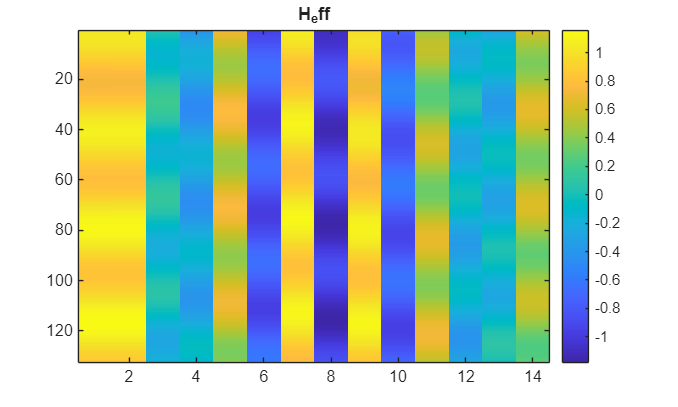

% H_eff when we compensate symbol-wise
for n = 1:14
    % t_n = (n-1) * 256 / simParameters.SampleRate;  % ← This is TIME
    % t_n = (n-1) * 256 ;
    if n==1
        t_n = ofdmInfo.CyclicPrefixLengths(n);
    else
        t_n = ofdmInfo.CyclicPrefixLengths(n) + ofdmInfo.SymbolLengths(n-1);
    end
    t_n = t_n / simParameters.SampleRate;
    % Apply phase that accumulates with TIME
    H_perfect_n(:, n) = hEstPerfect(:, n) * exp(-1i*2*pi*satelliteDopplerShift*t_n);
end
figure; imagesc(real(H_perfect_n)); colorbar; title('H_eff')

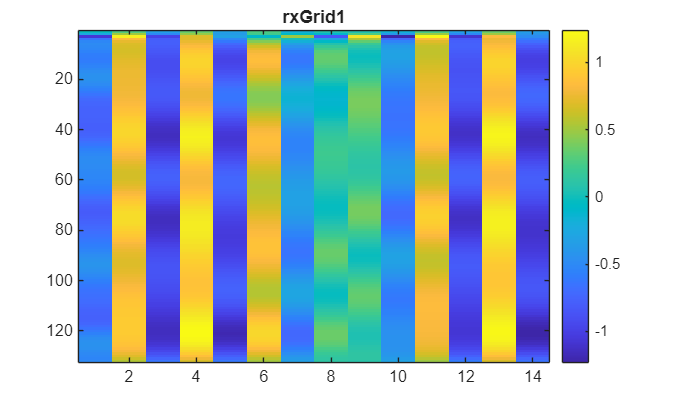

% check to see if rxGrid1 equal to hEstPerfect channel grid
figure; imagesc(real(rxGrid1)); colorbar; title('rxGrid1')

the top subcarrier elements are not similar to the perfect channel 

### Check the effective channel when we compensate sample-wise

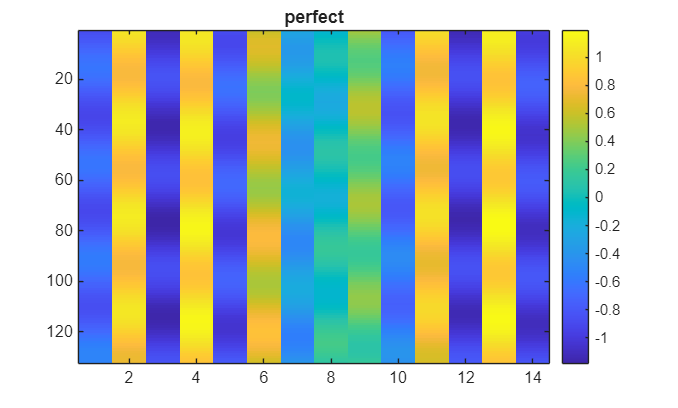

% sample-wise Doppler precompensate
t = (0:size(txWaveform1,1)-1)'/simParameters.SampleRate;
txWaveform2 = txWaveform1.*exp(1j*2*pi*(-satelliteDopplerShift)*t);

[rxWaveform2,pathGains] = channel(txWaveform2);
pathFilters = getPathFilters(channel);
offset = nrPerfectTimingEstimate(pathGains,pathFilters);
rxGrid2 = nrOFDMDemodulate(ue,rxWaveform2(1+offset:end,:));
hEstPerfect2 = nrPerfectChannelEstimate(ue,pathGains,pathFilters,offset);    

figure; imagesc(real(hEstPerfect2)); colorbar; title('perfect')

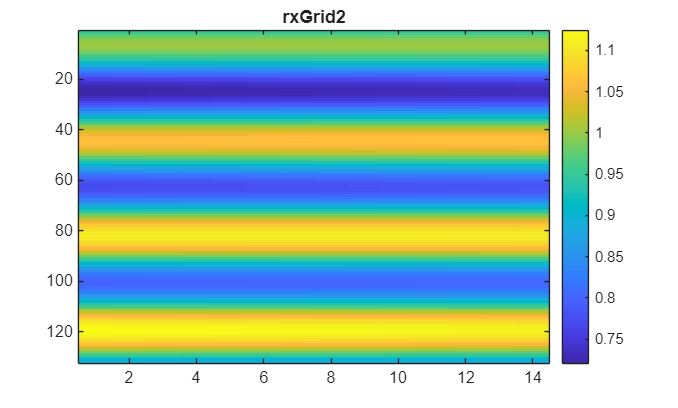

figure; imagesc(real(rxGrid2)); colorbar; title('rxGrid2')